# SNW_A4CHK_UNEMP_BISEC_VEC Morer Dense Solution Analysis

This is the example vignette for function:  [**snw_a4chk_unemp_bisec_vec**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/splanner/snw_a4chk_unemp_bisec_vec.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This function solves for the V(states, check) for individuals working. Morer Dense solution. Bisection, most time for the test here taken to genereate the income matrixes. But these can be generated out of the check loops.

## Test SNW_A4CHK_UNEMP_BISEC_VEC Defaults Morer Dense

Call the function with defaults.

mp_params = snw_mp_param('default_moredense');
mp_controls = snw_mp_control('default_test');
mp_controls('bl_print_vfi') = false;
mp_controls('bl_timer') = true;
[V_ss,~,cons_ss,~] = snw_vfi_main_bisec_vec(mp_params, mp_controls);

Elapsed time is 909.446277 seconds.
Completed SNW_VFI_MAIN;SNW_MP_PARAM=default_moredense;SNW_MP_CONTROL=default_test


welf_checks = 2;
xi=0.5;
b=0;
TR = 100/58056;
mp_params('TR') = TR;
mp_params('xi') = xi;
mp_params('b') = b;
[V_unemp,~,cons_unemp,~] = snw_vfi_main_bisec_vec(mp_params, mp_controls, V_ss);

Elapsed time is 978.398094 seconds.
Completed SNW_VFI_MAIN 1 PERIOD UNEMP SHK;SNW_MP_PARAM=default_moredense;SNW_MP_CONTROL=default_test


[V_U, C_U] = snw_a4chk_unemp_bisec_vec(welf_checks, V_unemp, cons_unemp, mp_params, mp_controls);

Elapsed time is 361.540525 seconds.
Completed SNW_A4CHK_UNEMP_BISEC_VEC;welf_checks=2;TR=0.0017225;xi=0.5;b=0;SNW_MP_PARAM=default_moredense;SNW_MP_CONTROL=default_test
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_container_map ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                         i    idx    ndim      numel      rowN      colN           sum           mean          std        coefvari       min           max   
                         _    ___    ____    _________    ____    _________    ___________    __________    __________    ________

mn_V_U_gain_check = V_U - V_unemp;
mn_MPC_U_gain_share_check = (C_U - cons_unemp)./(welf_checks*mp_params('TR'));

## Morer Dense Param Results Define Frames

Define the matrix dimensions names and dimension vector values. Policy and Value Functions share the same ND dimensional structure.

% Grids: 
age_grid = 18:100;
agrid = mp_params('agrid')';
eta_H_grid = mp_params('eta_H_grid')';
eta_S_grid = mp_params('eta_S_grid')';
ar_st_eta_HS_grid = string(cellstr([num2str(eta_H_grid', 'hz=%3.2f;'), num2str(eta_S_grid', 'wz=%3.2f')]));
edu_grid = [0,1];
marry_grid = [0,1];
kids_grid = (1:1:mp_params('n_kidsgrid'))';
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'savings', agrid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'eta', 1:length(eta_H_grid)});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'edu', edu_grid});
cl_mp_datasetdesc{5} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{6} = containers.Map({'name', 'labval'}, {'kids', kids_grid});

## Analyze Difference in V and C with Check

The difference between V and V with Check, marginal utility gain given the check.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('cl_st_xtitle') = {'Savings States, a'};
mp_support_graph('st_legend_loc') = 'eastoutside';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('it_legend_select') = 21; % how many shock legends to show
mp_support_graph('cl_colors') = 'jet';

#### MEAN(MN_V_GAIN_CHECK(A,Z))

Tabulate value and policies along savings and shocks:

% Set
ar_permute = [1,4,5,6,3,2];
% Value Function
st_title = ['MEAN(MN_V_U_GAIN_CHECK(A,Z)), welf_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR'))];
tb_az_v = ff_summ_nd_array(st_title, mn_V_U_gain_check, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_V_U_GAIN_CHECK(A,Z)), welf_checks=2, TR=0.0017225  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings    mean_eta_1    mean_eta_2    mean_eta_3    mean_eta_4    mean_eta_5    mean_eta_6    mean_eta_7    mean_eta_8    mean_eta_9    mean_eta_10    mean_eta_11    mean_eta_12    mean_eta_13    mean_eta_14    mean_eta_15    mean_eta_16    mean_eta_17    mean_eta_18    mean_eta_19    mean_eta_20    mean_eta_21    mean_eta_22    mean_eta_23    mean_eta_24    mean_eta_25    mean_eta_26    mean_eta_27

% Consumption
st_title = ['MEAN(MN_MPC_U_GAIN_CHECK(A,Z)), welf_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR'))];
tb_az_c = ff_summ_nd_array(st_title, mn_MPC_U_gain_share_check, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_MPC_U_GAIN_CHECK(A,Z)), welf_checks=2, TR=0.0017225  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings    mean_eta_1    mean_eta_2    mean_eta_3    mean_eta_4    mean_eta_5    mean_eta_6    mean_eta_7    mean_eta_8    mean_eta_9    mean_eta_10    mean_eta_11    mean_eta_12    mean_eta_13    mean_eta_14    mean_eta_15    mean_eta_16    mean_eta_17    mean_eta_18    mean_eta_19    mean_eta_20    mean_eta_21    mean_eta_22    mean_eta_23    mean_eta_24    mean_eta_25    mean_eta_26    mean_eta_27

Graph Mean Values:

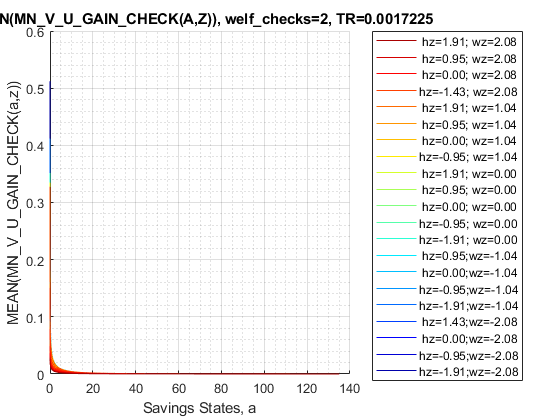

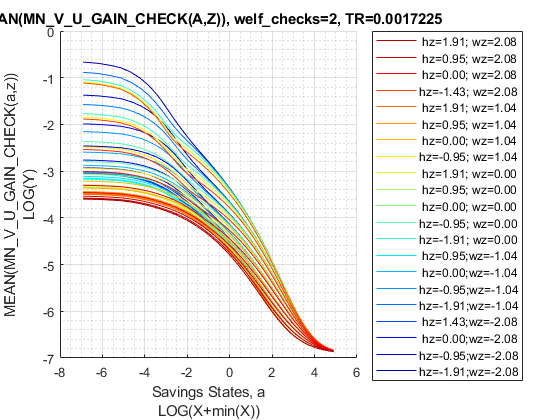

st_title = ['MEAN(MN\_V\_U\_GAIN\_CHECK(A,Z)), welf\_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR')) ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_V\_U\_GAIN\_CHECK(a,z))'};
ff_graph_grid((tb_az_v{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

Graph Mean Consumption (***MPC: Share of Check Consumed***):

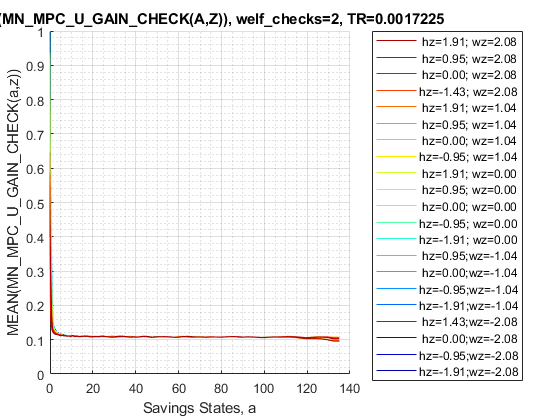

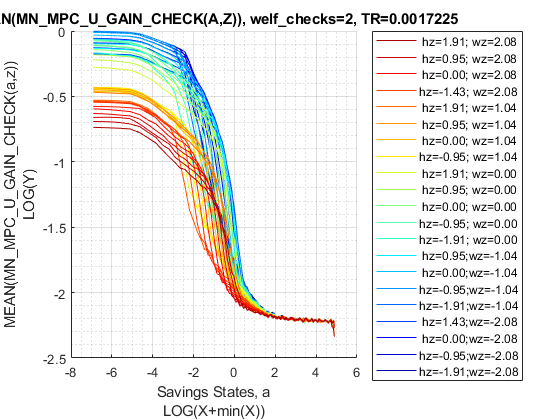

st_title = ['MEAN(MN\_MPC\_U\_GAIN\_CHECK(A,Z)), welf\_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR')) ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_MPC\_U\_GAIN\_CHECK(a,z))'};
ff_graph_grid((tb_az_c{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

## Analyze Kids and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = [...
    "k0M0", "K1M0", "K2M0", "K3M0", "K4M0", ...
    "k0M1", "K1M1", "K2M1", "K3M1", "K4M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {...
    'o', 'd' ,'s', 'x', '*', ...
    'o', 'd', 's', 'x', '*'};
mp_support_graph('cl_colors') = {...
    'red', 'red', 'red', 'red', 'red'...
    'blue', 'blue', 'blue', 'blue', 'blue'};

#### MEAN(VAL(KM,J)), MEAN(AP(KM,J)), MEAN(C(KM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,4,1,6,5];
% Value Function
st_title = ['MEAN(MN_V_U_GAIN_CHECK(KM,J)), welf_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR'))];
tb_az_v = ff_summ_nd_array(st_title, mn_V_U_gain_check, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_V_U_GAIN_CHECK(KM,J)), welf_checks=2, TR=0.0017225  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_18    mean_age_19    mean_age_20    mean_age_21    mean_age_22    mean_age_23    mean_age_24    mean_age_25    mean_age_26    mean_age_27    mean_age_28    mean_age_29    mean_age_30    mean_age_31    mean_age_32    mean_age_33    mean_age_34    mean_age_35    mean_age_36    mean_age_37    mean_age_38    mean_age_39    mean_age_40    mean_age_41    mean_age_42    mean_age_43

% Consumption Function
st_title = ['MEAN(MN_MPC_U_GAIN_CHECK(KM,J)), welf_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR'))];
tb_az_c = ff_summ_nd_array(st_title, mn_MPC_U_gain_share_check, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_MPC_U_GAIN_CHECK(KM,J)), welf_checks=2, TR=0.0017225  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_18    mean_age_19    mean_age_20    mean_age_21    mean_age_22    mean_age_23    mean_age_24    mean_age_25    mean_age_26    mean_age_27    mean_age_28    mean_age_29    mean_age_30    mean_age_31    mean_age_32    mean_age_33    mean_age_34    mean_age_35    mean_age_36    mean_age_37    mean_age_38    mean_age_39    mean_age_40    mean_age_41    mean_age_42    mean_age_43

Graph Mean Values:

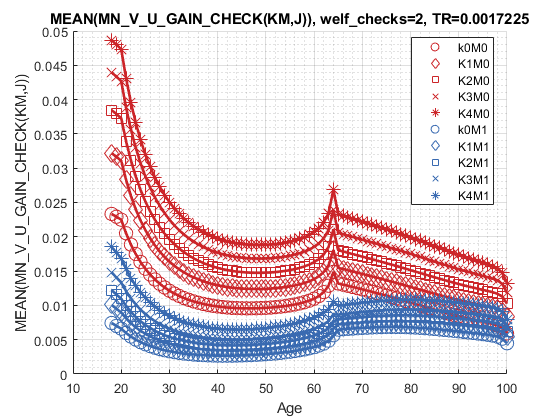

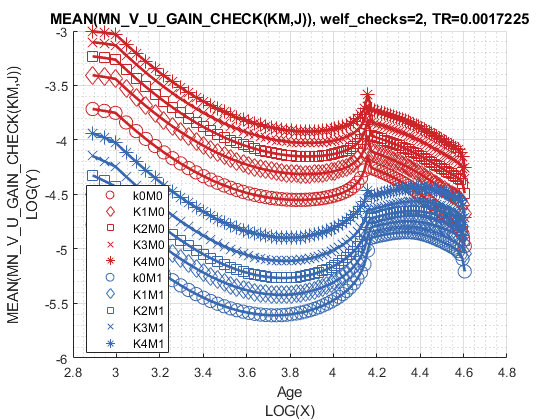

st_title = ['MEAN(MN\_V\_U\_GAIN\_CHECK(KM,J)), welf\_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR')) ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_V\_U\_GAIN\_CHECK(KM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption (***MPC: Share of Check Consumed***):

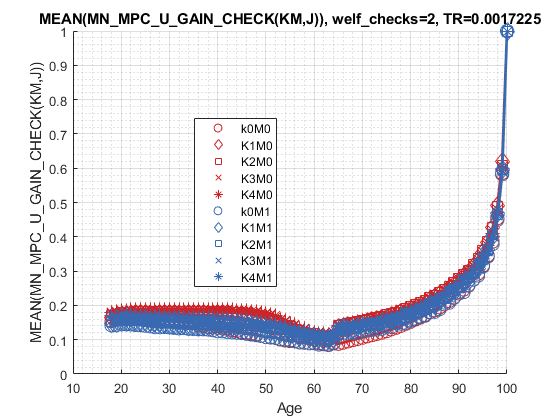

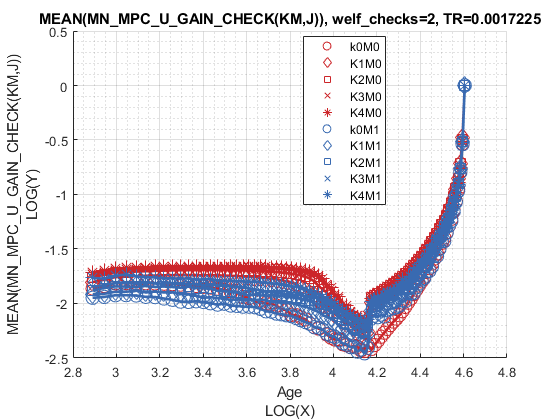

st_title = ['MEAN(MN\_MPC\_U\_GAIN\_CHECK(KM,J)), welf\_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR')) ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_MPC\_U\_GAIN\_CHECK(KM,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

## Analyze Education and Marriage

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["E0M0", "E1M0", "E0M1", "E1M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {'*', 'p', '*','p' };
mp_support_graph('cl_colors') = {'red', 'red', 'blue', 'blue'};

#### MEAN(VAL(EM,J)), MEAN(AP(EM,J)), MEAN(C(EM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,6,1,4,5];
% Value Function
st_title = ['MEAN(MN_V_U_GAIN_CHECK(EM,J)), welf_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR'))];
tb_az_v = ff_summ_nd_array(st_title, mn_V_U_gain_check, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_V_U_GAIN_CHECK(EM,J)), welf_checks=2, TR=0.0017225  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_18    mean_age_19    mean_age_20    mean_age_21    mean_age_22    mean_age_23    mean_age_24    mean_age_25    mean_age_26    mean_age_27    mean_age_28    mean_age_29    mean_age_30    mean_age_31    mean_age_32    mean_age_33    mean_age_34    mean_age_35    mean_age_36    mean_age_37    mean_age_38    mean_age_39    mean_age_40    mean_age_41    mean_age_42    mean_age_43

% Consumption
st_title = ['MEAN(MN_MPC_U_GAIN_CHECK(EM,J)), welf_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR'))];
tb_az_c = ff_summ_nd_array(st_title, mn_MPC_U_gain_share_check, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_MPC_U_GAIN_CHECK(EM,J)), welf_checks=2, TR=0.0017225  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_18    mean_age_19    mean_age_20    mean_age_21    mean_age_22    mean_age_23    mean_age_24    mean_age_25    mean_age_26    mean_age_27    mean_age_28    mean_age_29    mean_age_30    mean_age_31    mean_age_32    mean_age_33    mean_age_34    mean_age_35    mean_age_36    mean_age_37    mean_age_38    mean_age_39    mean_age_40    mean_age_41    mean_age_42    mean_age_43

Graph Mean Values:

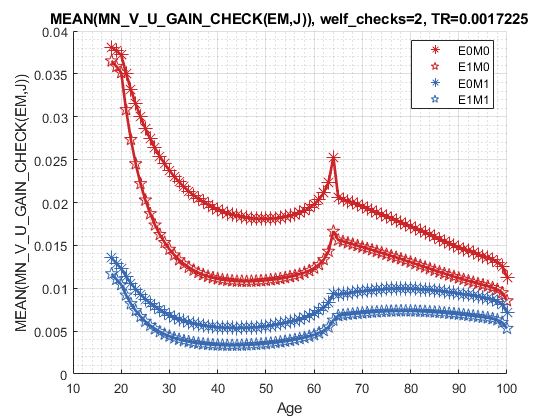

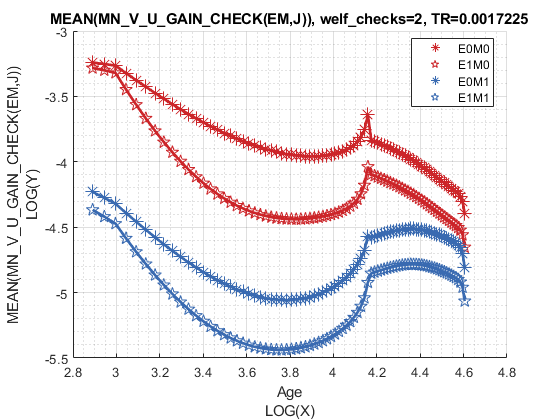

st_title = ['MEAN(MN\_V\_U\_GAIN\_CHECK(EM,J)), welf\_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR')) ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_V\_U\_GAIN\_CHECK(EM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption (***MPC: Share of Check Consumed***):

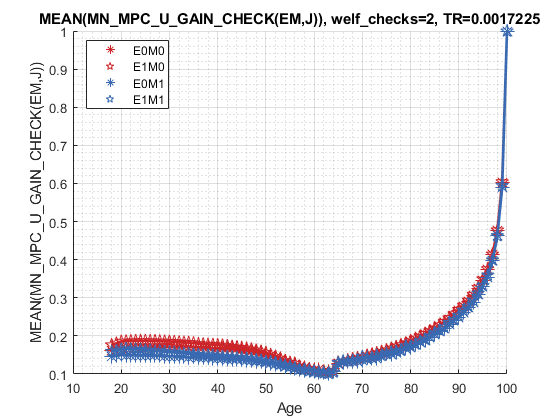

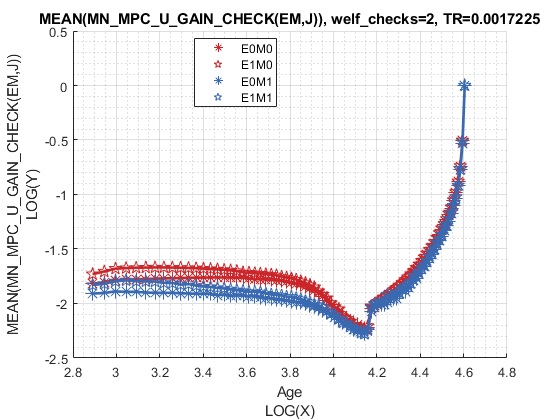

st_title = ['MEAN(MN\_MPC\_U\_GAIN\_CHECK(EM,J)), welf\_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR')) ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_MPC\_U\_GAIN\_CHECK(EM,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);